# Manual ifft generation using fft

n = 0:20;
%original signal
x_t = sin(0.2*pi*n);
% Start timing the manual IFFT process
tic;
% Fourier Transform using fft
X = fft(x_t);
% Take the conjugate of the FFT result
X_conjugate = conj(X);

% Compute the FFT of the conjugate
myifft = fft(X_conjugate);
% End timing the manual IFFT process
manual_time = toc;


%Compute the IFFT using MATLAB's built-in function for comparison
% Start timing the built-in IFFT process
tic;
matiff = ifft(X);

% End timing the built-in IFFT process
builtin_time = toc;

% Plot original signal
subplot(4, 1, 1);
stem(n, x_t, 'filled');
xlabel('n');
ylabel('x[n]');
title('Original Signal x[n] = sin(0.2\pi n)');
grid on;

% ffft transform
subplot(4, 1, 2);
stem(n, X, 'filled');

ylabel('Reconstructed x[n]');
title('Fourier Transform signal');
grid on;

% matlab iff plot
subplot(4, 1, 3);
stem(n, matiff, 'filled');
ylabel('x[n]');
title('Reconstructed Signal using built-in IFFT');
grid on;
% 
subplot(4, 1, 4);
stem(n, myifft, 'filled');

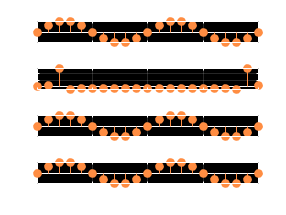

xlabel('n');
ylabel('x[n]');
title('Manually Reconstructed Signal using FFT');
grid on;

whitebg('k');

% Display error between original and manually reconstructed signals
manual_error = norm(x_t - myifft);
disp(['Manual Reconstruction Error: ', num2str(manual_error)]);

Manual Reconstruction Error: 63.2456



% Display error between original and built-in IFFT reconstructed signals
builtin_error = norm(x_t - matiff);
disp(['Built-in IFFT Reconstruction Error: ', num2str(builtin_error)]);

Built-in IFFT Reconstruction Error: 7.3648e-16


% Determine which method is optimized
if manual_time < builtin_time
    disp('Manual IFFT is more optimized.');
else
    disp('Built-in IFFT is more optimized.');
end

Built-in IFFT is more optimized.
